# Using a Deep Learning Network to Classify Brain Tumors from MRI images

Thang Gang Group Members: Rayan Dharia, Katie Garcia, Camryn Gerspach, Michael Olagbiyan

Course: BME3053C Computer Applications of BME

Term: Fall 2022

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

December 3rd, 2022

This program is a MATLAB live script walkthrough of the process to use a deep learning network to classify brain MRI images. The result also gives a detailed explanation of what to do next.

clc; clear; close all;

## Load Network and Determine Image Input Size

load DetectTumor.mat;
inputSize = net.Layers(1).InputSize;

## Create the Datastore and Apply Preprocessing

Once the datastore of the testing images are created, apply resizing and convert all images to 3D arrays using an augmented image datastore. 

folder = input("Name of the folder containing image(s): ","s");
imds = imageDatastore(folder,'IncludeSubfolders', true, 'LabelSource', 'foldernames');
augimds = augmentedImageDatastore(inputSize(1:2),imds,"ColorPreprocessing","gray2rgb");

## Classify the Image(s) in the Augmented Image Datastore

Y = classify(net,augimds);

## Generate a Random Number

This section is really only used for the Testing data set provided. It chooses a random image from the augmented image datastore. The variable "i" can be set to 1 if there is only one image in the folder.

i = randi([0 , numel(augimds.Files)],1,1);

## Generate the Output

This section is where the image output is generated.

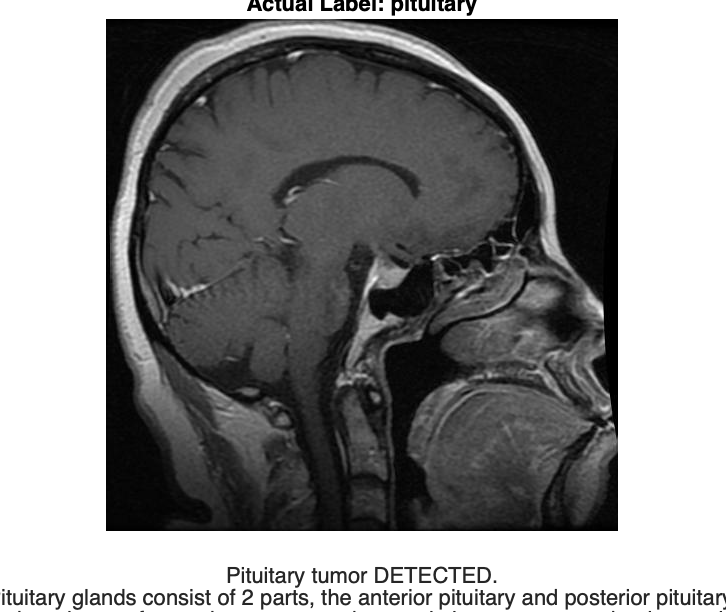

figure;
imshow(augimds.Files{i});
title(["Predicted Label: " + string(Y(i)),"Actual Label: " + string(imds.Labels(i))])

for i = i
if string(Y(i)) == "pituitary"
    xlabel(["Pituitary tumor DETECTED.","Pituitary glands consist of 2 parts, the anterior pituitary and posterior pituitary.","The Pituitary Glands are responsible for the release of many hormones, and most pituitary tumors are benign yet in rare cases the tumors are cancerous.","Please go to the website below to learn more.","Further evaluation is needed for confirmation.","https://www.cancer.org/cancer/pituitary-tumors/about/what-is-pituitary-tumor.html"])
elseif string(Y(i)) == "glioma"
    xlabel(["Glioma DETECTED.","Gliomas originate from glial cells, and there are many kinds of gliomas.","Gliomas are the most common types of primary brain tumors making up about 33% of brain tumors.","Depending on the growth potential and aggressiveness the grades of gliomas may differ.","Please go to the website below to learn more. Further evaluation is needed for confirmation of type and grade of glioma.","https://www.hopkinsmedicine.org/health/conditions-and-diseases/gliomas"])
elseif string(Y(i)) == "meningioma"
    xlabel(["Meningioma DETECTED.","Meningioma is a central nervous system tumor meaning the brain and the spinal cord is where it originates from.","There are three different grades of meningiomas.","Grade I meningiomas are the most common and the cells are growing slowly.","Grade II meningiomas are mid-grade and have a higher chance of coming back after removal.","Grade III meningiomas have extremely fast-growing cells and are malignant.","Please go to the website below to learn more.","Further evaluation is needed for confirmation and grade of meningioma.","https://www.cancer.gov/rare-brain-spine-tumor/tumors/meningioma#:~:text=A%20meningioma%20is%20a%20primary,grade%20meningiomas%20are%20very%20rare"])
else
    xlabel(["No tumor detected.","Further evaluation is needed to confirm."])
end
end